# Simple Pendulum

## Step 7: Determine Equations of Motion

Equation of motion is


$$\ddot{\theta}=-\frac{g}{L}\sin{\theta}$$


## Step 8: Solve the EOM, Solve the Problem

Re-write as first-order ODEs. Define state variables


$$s_1=\theta \\
s_2=\dot{\theta}
$$


and then the equations of motion are


$$\dot{s}_1=s_2 \\
\dot{s}_2=-\frac{g}{L}\sin{s_1}$$


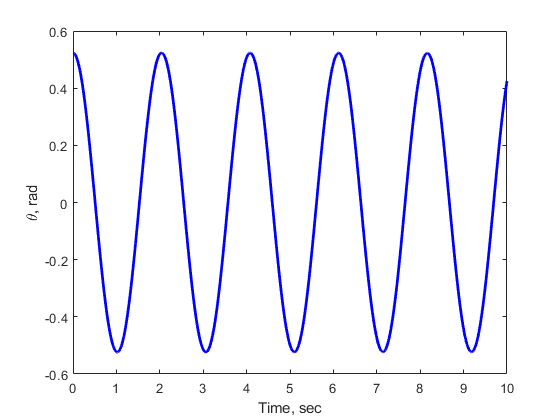

g = 9.81; % gravitational constant, m/s^2
L = 1; % length, m
[T S] = ode45(@(t,s)eom(t,s,g,L),linspace(0,10,1001),[pi/6,0]);
plot(T,S(:,1),'-b','linewidth',2)
xlabel('Time, sec')
ylabel('\theta, rad')

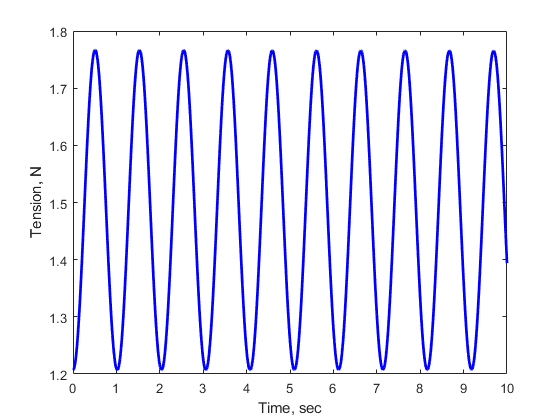

m = 5*(1/16)*(1/2.2); % mass, convert 5 oz to kg
Tension = m*(L*S(:,2).^2+g*cos(S(:,1)));
plot(T,Tension,'-b','linewidth',2)
xlabel('Time, sec')
ylabel('Tension, N')

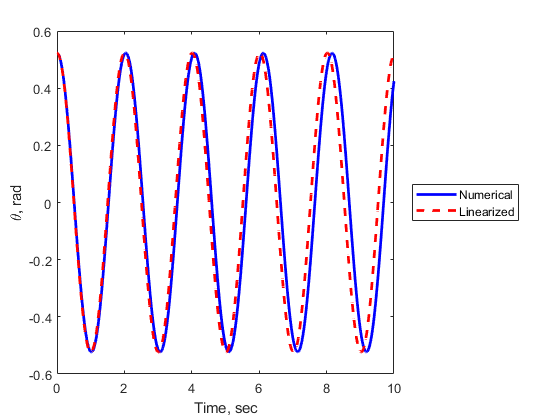

ThetaLinear = pi/6*cos(sqrt(g/L)*T);
plot(T,S(:,1),'-b',T,ThetaLinear,'--r','linewidth',2)
xlabel('Time, sec')
ylabel('\theta, rad')
legend('Numerical','Linearized','Location','EastOutside')

function sdot = eom(~,s,g,L)
sdot(1,1) = s(2);
sdot(2,1) = -g/L*sin(s(1));
end